 **Project**

Brandon Freiberger - 260739743

Theo Janson - 260868223

David Schrier - 260827890

clc;
clear;

**PART A**

Linearly Spaced Data

a = 0;
b = 2 * pi;
N = 300;
deg = 32;

[input, output] = Linear_SpacedData(a, b, N);

[fp, fl] = approximate(input, output, deg);

Condition Number of Polynomial Matrix: 


Polynominal_cond = 1.4317e+34

Condition Number of Legendre Matrix


Legendre_cond = 6.5550e+41

Linearly Spaced Data


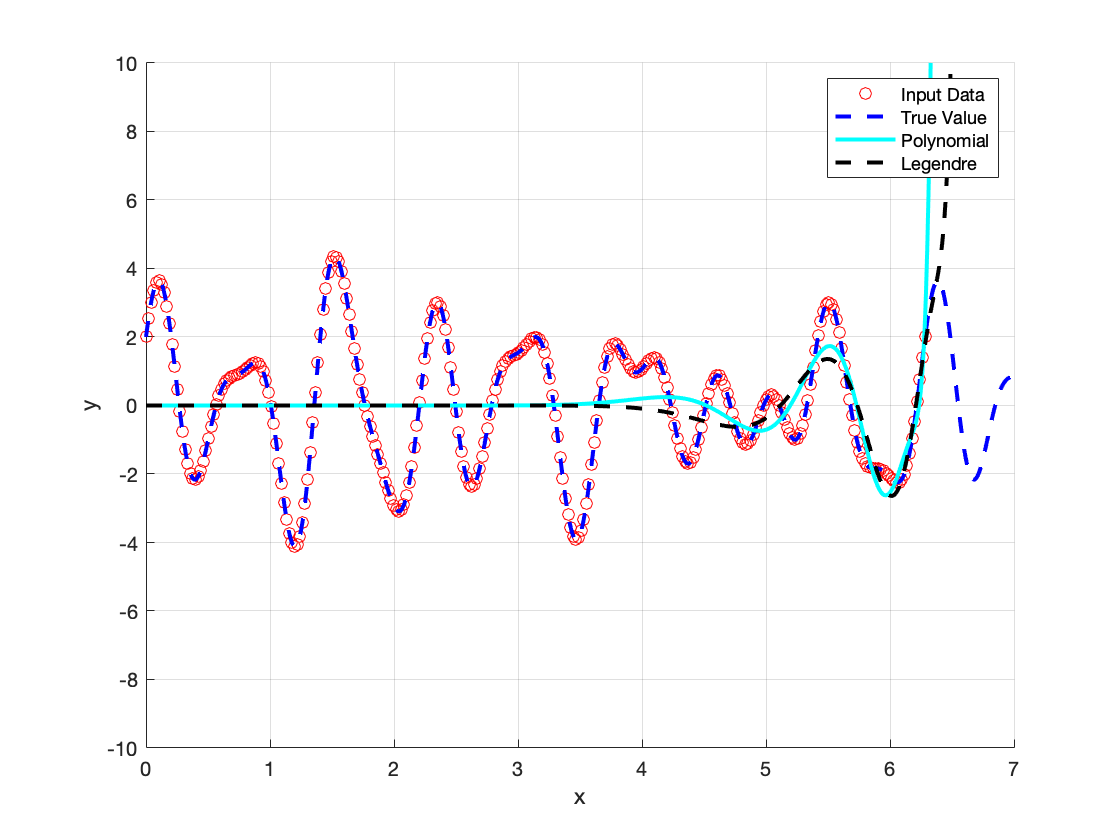

plot_results(input, output, fp, fl, 'Linearly Spaced Data')

[polynomial_similarity, legendre_similarity] = cosine_similarities(fp,fl)

polynomial_similarity = 0.2980

legendre_similarity = 0.2714

Chebyshev Spacing:

a = 0;
b = 2 * pi;
N = 300;
deg = 32;

[input, output] = Chebyshev_Nodes_Data(a, b, N);

[fp, fl] = approximate(input, output, deg);

Condition Number of Polynomial Matrix: 


Polynominal_cond = 1.5301e+34

Condition Number of Legendre Matrix


Legendre_cond = 8.5242e+41

Chebyshev Spaced


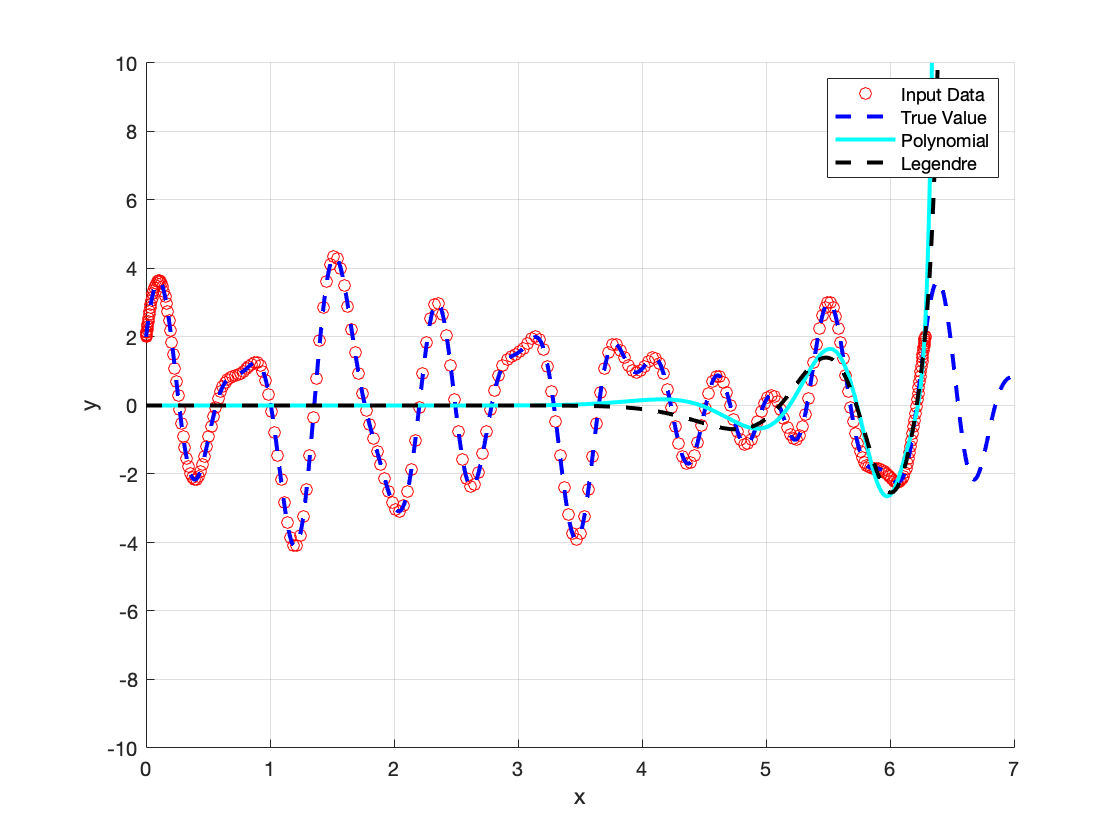

plot_results(input, output, fp, fl, 'Chebyshev Spaced')


[polynomial_similarity, legendre_similarity] = cosine_similarities(fp,fl)

polynomial_similarity = 0.2958

legendre_similarity = 0.2695

Random Spacing:

a = 0;
b = 2 * pi;
N = 300;
deg = 32;

[input, output] = RandomlySampled_Data(a, b, N);

[fp, fl] = approximate(input, output, deg);

Condition Number of Polynomial Matrix: 


Polynominal_cond = 2.3480e+33

Condition Number of Legendre Matrix


Legendre_cond = 2.0425e+42

Randomly Spaced Data


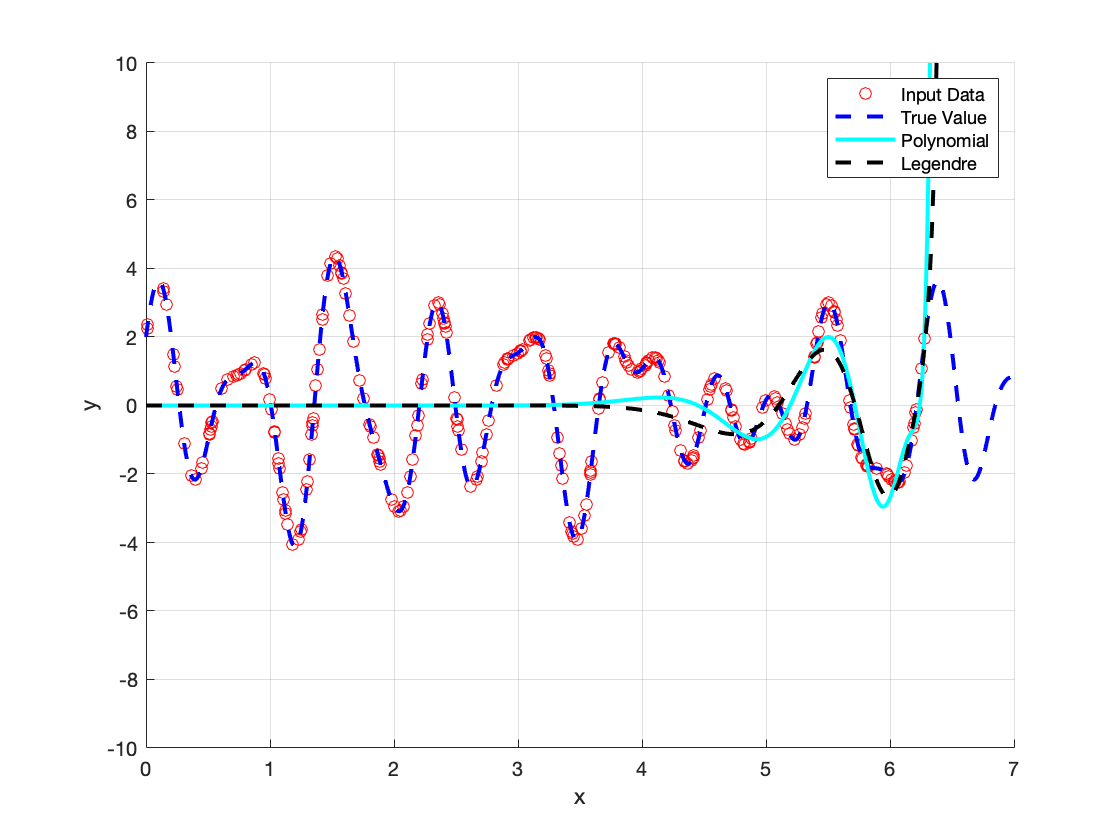

plot_results(input, output, fp, fl, 'Randomly Spaced Data')


[polynomial_similarity, legendre_similarity] = cosine_similarities(fp,fl)

polynomial_similarity = 0.2986

legendre_similarity = 0.2676

Roots of Legrendre Polynomial Spacing:

a = 0;
b = 2 * pi;
N = 300;
deg = 32;

[input, output] = Legendre_Roots_Data(b, N);

[fp, fl] = approximate(input, output, deg);

Condition Number of Polynomial Matrix: 


Polynominal_cond = 8.3032e+33

Condition Number of Legendre Matrix


Legendre_cond = 2.8573e+42

Roots of Legendre Polynomial


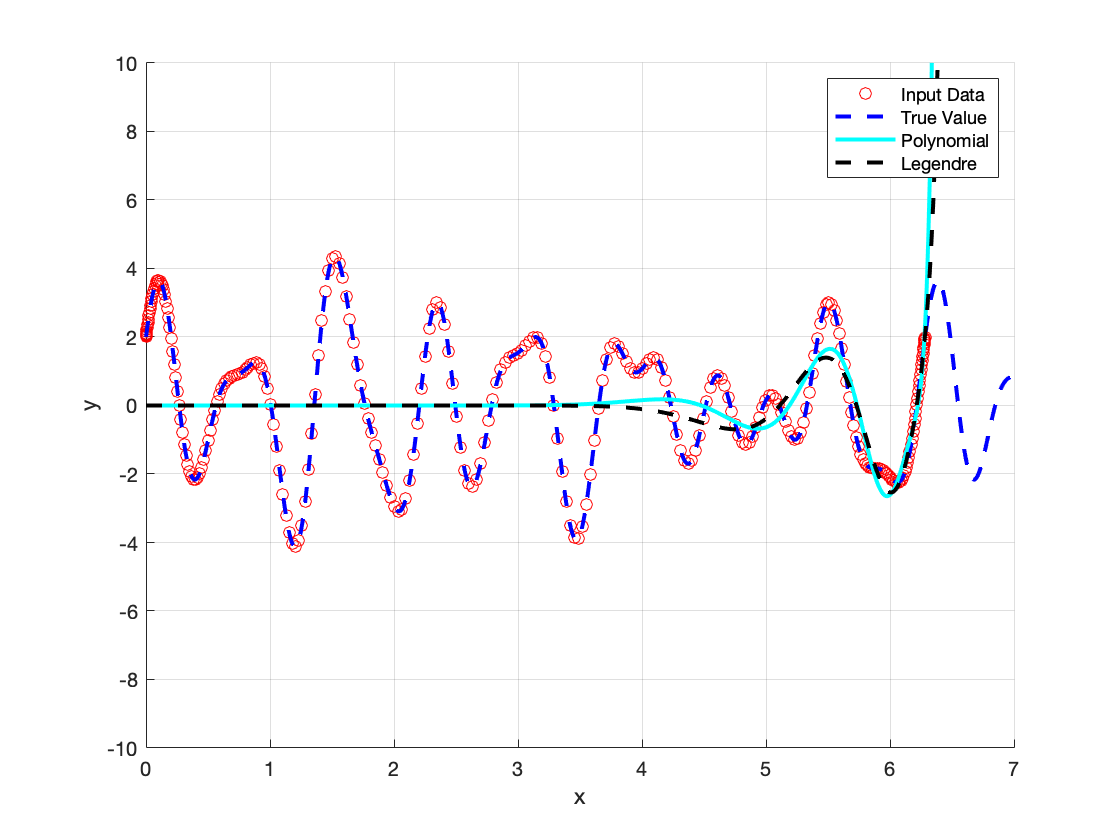

plot_results(input, output, fp, fl, 'Roots of Legendre Polynomial')


[polynomial_similarity, legendre_similarity] = cosine_similarities(fp,fl)

polynomial_similarity = 0.2959

legendre_similarity = 0.2695

**PART B: Scaling**

Linearly Spaced Data

a = 0;
b = 2 * pi;
N = 300;
deg = 32;

[input, output] = Linear_SpacedData(a, b, N);

[fp_scaled, fl_scaled, input_scaled, output_scaled] = approximateB(input, output, deg);

Condition Number of Polynomial Matrix: 


ans = 6.1029e+11

Condition Number of Legendre Matrix


ans = 8.0238

Linearly Spaced Data, Scaled


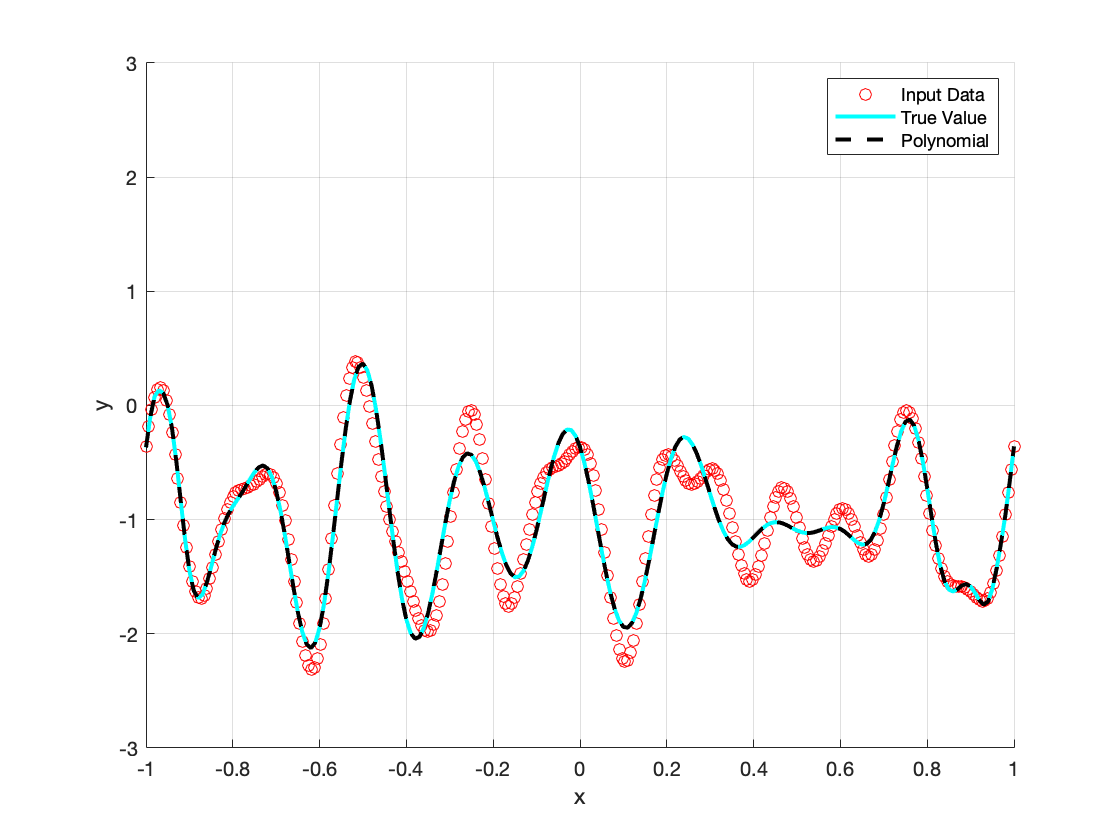

plot_resultsB(input_scaled, output_scaled, fp_scaled, fl_scaled, 'Linearly Spaced Data, Scaled')

Chebyshev Spacing:

a = 0;
b = 2 * pi;
N = 300;
deg = 32;

[input, output] = Chebyshev_Nodes_Data(a, b, N);

[fp_scaled, fl_scaled, input_scaled, output_scaled] = approximateB(input, output, deg);

Condition Number of Polynomial Matrix: 


ans = 8.9050e+11

Condition Number of Legendre Matrix


ans = 10.4650

Chebyshov Spacing, Scaled


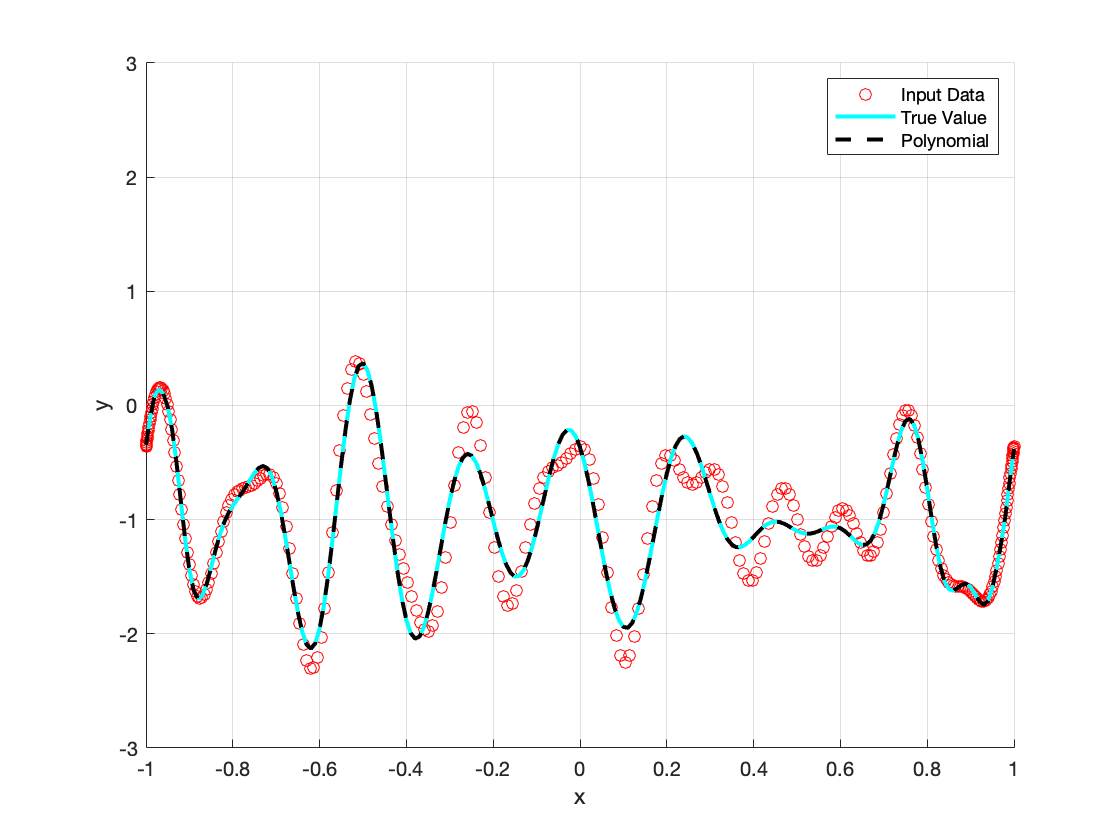

plot_resultsB(input_scaled, output_scaled, fp_scaled, fl_scaled, 'Chebyshov Spacing, Scaled')

Random Spacing:

a = 0;
b = 2 * pi;
N = 300;
deg = 32;

[input, output] = RandomlySampled_Data(a, b, N);

[fp_scaled, fl_scaled, input_scaled, output_scaled] = approximateB(input, output, deg);

Condition Number of Polynomial Matrix: 


ans = 8.0065e+11

Condition Number of Legendre Matrix


ans = 35.0534

Random Spacing, Scaled


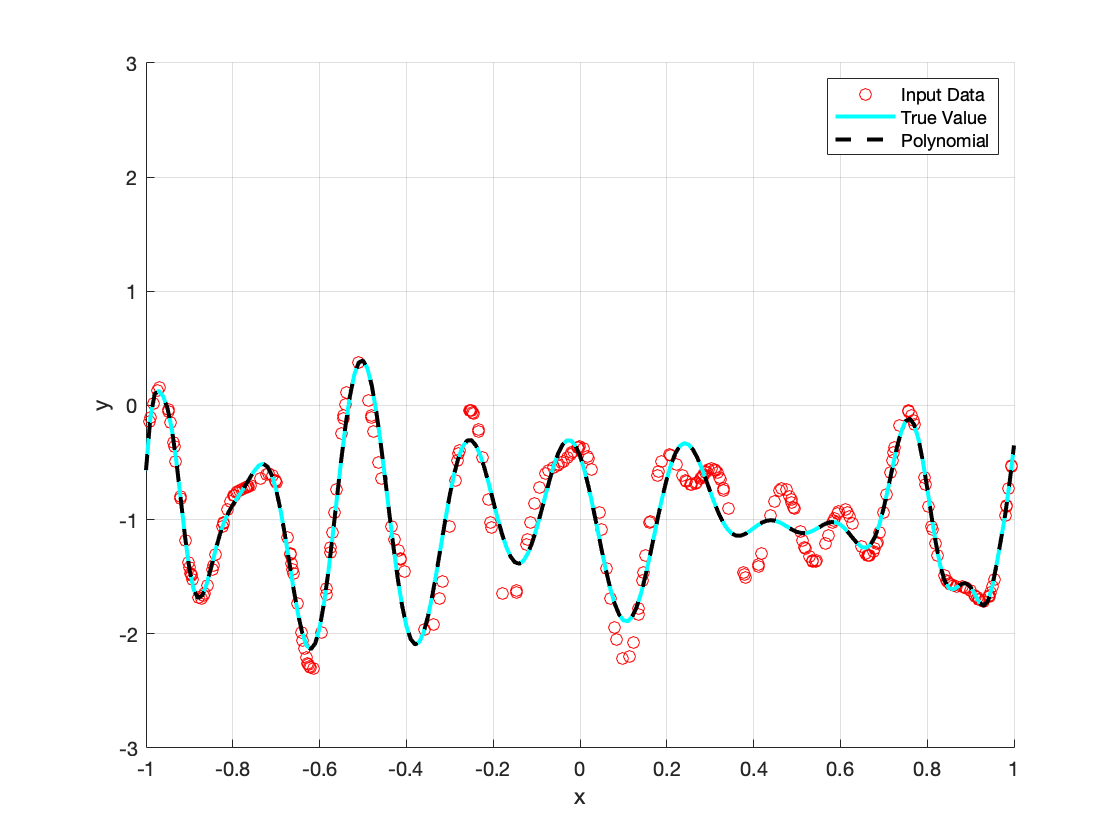

plot_resultsB(input_scaled, output_scaled, fp_scaled, fl_scaled, 'Random Spacing, Scaled')

Roots of Legrendre Polynomial Spacing:

a = 0;
b = 2 * pi;
N = 300;
deg = 32;

[input, output] = Legendre_Roots_Data(b, N);

[fp_scaled, fl_scaled, input_scaled, output_scaled] = approximateB(input, output, deg);

Condition Number of Polynomial Matrix: 


ans = 8.8178e+11

Condition Number of Legendre Matrix


ans = 10.3133

Roots of Legendre Polynomial Spacing, Scaled


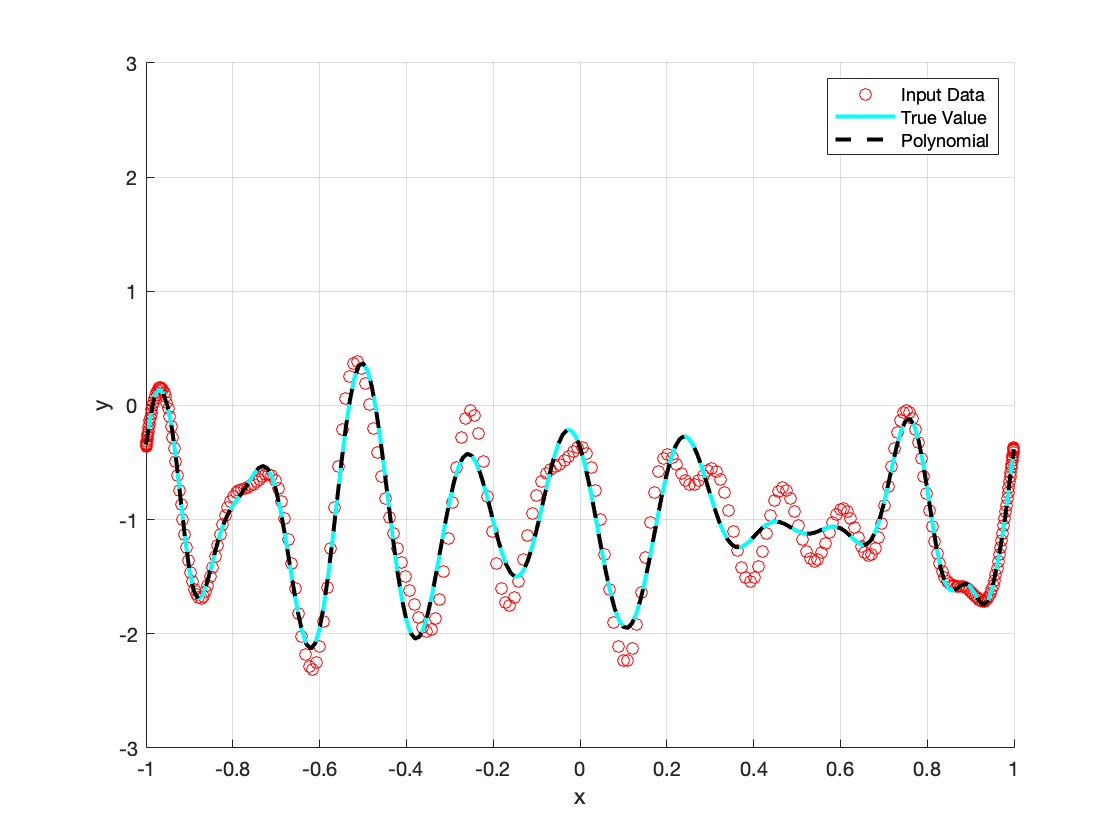


plot_resultsB(input_scaled, output_scaled, fp_scaled, fl_scaled, 'Roots of Legendre Polynomial Spacing, Scaled')

Function to compute the cosine similarities between Polynomial estimate and Legendre estimate, and G(x)

function [fp_similarity, fl_similarity] = cosine_similarities(fp, fl)
    x_new = 0:0.01:9.99;
    x_new = x_new';
    g_x = sin(5*x_new) +2*cos(8*x_new) +sin(9*x_new)+ (sin(14*x_new));
    
    fp = fp(1:size(x_new)*0.599);
    gx = g_x(1:size(x_new)*0.599);
    fl = fl(1:size(x_new)*0.599);
    
    fp_similarity = dot(fp, gx) / (norm(fp) * norm(gx));
    fl_similarity = dot(fl, gx) / (norm(fl) * norm(gx));
end

Function to estimate G(x) using Polynomial Matrix and Legendre Matrix. Calculates condition number of these matrices and returns the vectors estimates (coefficients). 

function [fp, fl] = approximate(input, output, deg)

    M_poly = PolynomialMatrix(input, deg);
    M_leg = LegendreMatrix(input, deg);
    
    disp('Condition Number of Polynomial Matrix: ')
    Polynominal_cond = cond(M_poly)
    disp('Condition Number of Legendre Matrix')
    Legendre_cond = cond(M_leg)
    
    [Q_poly, R_poly] = qr(M_poly);
    [Q_leg, R_leg] = qr(M_leg);
    A_poly = (Q_poly * R_poly) \ output;
    A_leg = (Q_leg * R_leg) \ output;
    
     x_new = 0:0.01:9.99;
     x_new = x_new';
     powers = 0:deg;
    
    fp = zeros(length(x_new),1);
    fl = zeros(length(x_new),1);
    for I = 1:length(powers)  
       fp = fp + A_poly(I) * x_new.^powers(I);
       fl = fl + A_leg(I) * legendreP(I-1, x_new);
    end
end



function [fc_scaled, fl_scaled, input_vector_scaled, output_vector_scaled] = approximateB(input_vector, output_vector, deg)

a = 0;
b = 2 * pi;

input_vector_scaled = 2/(b-a) * (input_vector - (a + b)/2);
output_vector_scaled = 2/(b-a) * (output_vector - (a + b)/2);

M_lin_spaced_scaled = PolynomialMatrix(input_vector_scaled, deg);
M_lin_spaced_leg_scaled = LegendreMatrix(input_vector_scaled, deg);


disp('Condition Number of Polynomial Matrix: ')
cond(M_lin_spaced_scaled)
disp('Condition Number of Legendre Matrix')
cond(M_lin_spaced_leg_scaled)

[Q_lin_spaced_scaled, R_lin_spaced_scaled] = qr(M_lin_spaced_scaled);
[Q_lin_spaced_leg_scaled, R_lin_spaced_leg_scaled] = qr(M_lin_spaced_leg_scaled);

A_lin_poly_scaled = (Q_lin_spaced_scaled * R_lin_spaced_scaled) \ output_vector_scaled;
A_lin_leg_scaled = (Q_lin_spaced_leg_scaled * R_lin_spaced_leg_scaled) \ output_vector_scaled;

x_new = -1:0.01:1;
x_new = x_new';
powers = 0:deg;
fc_scaled = zeros(length(x_new),1);
fl_scaled = zeros(length(x_new),1);


for I = 1:length(powers)  
   fc_scaled = fc_scaled + A_lin_poly_scaled(I) * x_new.^powers(I);
   fl_scaled = fl_scaled + A_lin_leg_scaled(I) * legendreP(I-1, x_new);
end

end














Plots the results. 


function plot_results(input, output, v1, v2, title)
    disp(title)
    figure
    hold on
    plot(input,output,'ro')
    x_new = 0:0.01:9.99;
    x_new = x_new';
    g_x = sin(5*x_new) + 2*cos(8*x_new) +sin(9*x_new)+ (sin(14*x_new));
    plot(x_new, g_x,'b--','Linewidth',2)
    plot(x_new, v1,'c','Linewidth',2)
    plot(x_new, v2, 'k--','Linewidth',2)
    hold off;
    xlabel('x')
    ylabel('y')
    xlim([0 7])
    ylim([-10 10])
 %   title(title)
    legend('Input Data', 'True Value', 'Polynomial', 'Legendre')
    grid on
end



function plot_resultsB(input, output, v1, v2, title)
    a = 0;
    b = 2 * pi;
    disp(title)
    figure
    hold on
    plot(input,output,'ro')
    x_new = -1:0.01:1;
    x_new = x_new';        
    plot(x_new, v1,'c','Linewidth',2)
    plot(x_new, v2, 'k--','Linewidth',2)
    hold off;
    xlabel('x')
    ylabel('y')
    xlim([-1 1])
    ylim([-3 3])
 %   title(title)
    legend('Input Data', 'True Value', 'Polynomial', 'Legendre')
    grid on
end



This function generates the linearly spaced input data points,x,  between the interval [a b]  then, provides the output data points by evaluating the true function at those data N is number of data points. x is column vector of input data. y is column vector of output

function[x,y] = Linear_SpacedData(a,b,N)
    x = linspace(a, b, N);
    data.x = linspace(a,b,N);
    y = sin(5*x) +2*cos(8*x) +sin(9*x)+ (sin(14*x));
    x = x(:);
    y = y(:);
end


This function generates the chebyshev nodes data points, x, between the interval [0 b] then, provides the output data points by evaluating the true function at those data points.


function[x,y] = Chebyshev_Nodes_Data(a,b,N)
% N is number of data points.
% x is column vector of input data.
% y is column vector of output data.
    k =0:N;
    x_cheb = cos(k*pi/N);x_cheb = x_cheb(end:-1:1);
    x = b*(x_cheb + 1)/2;
    y = sin(5*x) +2*cos(8*x) +sin(9*x)+ (sin(14*x));
    x = x(:);
    y = y(:);
end

This function provides N data points chossen using Legrendre Roots, then, provides the output data points by evaluating the true function at those data

function [x,y] = Legendre_Roots_Data(b,N)
% N is number of data points.
% x is column vector of input data.
% y is column vector of output data.
syms xp
x = vpasolve(legendreP(N,xp) == 0);
x = double(x);
x = b*(x + 1)/2;
y = sin(5*x) +2*cos(8*x) +sin(9*x)+ (sin(14*x));
x = x(:);
y = y(:);
end

This function provides N data points chossen using Random Sampling between interval [a b], then, provides the output data points by evaluating the true function  at those data.

function[x,y] = RandomlySampled_Data(a, b,N)
% N is number of data points.
% x is column vector of input data.
% y is column vector of output data.
    x = sort(unifrnd(a,b, N,1));
    y = sin(5*x) +2*cos(8*x) +sin(9*x)+ (sin(14*x));
    x = x(:);
    y = y(:);
end


Computes the n-th degree Legendre Matrx. 


function M = LegendreMatrix(x, n)
m = size(x,1);
M = zeros([m,n]);
    for j=1:n+1
        M(:,j)=legendreP(j-1,x);
    end
end


Computes the Polynomial matrix for a n-th degree polynomial. 

function M = PolynomialMatrix(x,n)
 % n is the degree of the polynomila
 % x is the vector of input data
 M = zeros(size(x, 1), n + 1);
 n_values = 0:1:n;
 M(1:end, 1) = 1;
 for i=1:size(M, 1)
     M(i, 2:end) = x(i, 1);
     M(i, 1:end) = M(i, 1:end) .^ n_values(1:end);
 end
end